**Análisis frecuencial**

En este ejemplo se analizará paso a paso la forma de analizar señales en el dominio de la frecuencia.

Los datos que se utilizarán corresponde a una simulación de un sensor inercial (IMU) de seis canales (acelerómetro y giróscopo). Hay datos del sensor estático y en movimiento.

Se inicia cargando los datos estáticos desde un archivo .csv. Se carga una matriz con seis columnas donde cada columna corresponde a un canal del sensor.

M = readmatrix('static.csv');
Ac_x = M(:,1);
Ac_y = M(:,2);
Ac_z = M(:,3);
 
Gy_x = M(:,4);
Gy_y = M(:,5);
Gy_z = M(:,6);

n = 0:length(Ac_x)-1;
figure()
subplot(2,3,1)

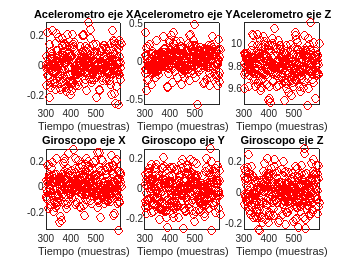

plot(n(300:599),Ac_x(300:599),'ro')
title('Acelerometro eje X')
xlabel('Tiempo (muestras)')
subplot(2,3,2)
plot(n(300:599),Ac_y(300:599),'ro')
title('Acelerometro eje Y')
xlabel('Tiempo (muestras)')
subplot(2,3,3)
plot(n(300:599),Ac_z(300:599),'ro')
title('Acelerometro eje Z')
xlabel('Tiempo (muestras)')

subplot(2,3,4)
plot(n(300:599),Gy_x(300:599),'ro')
title('Giroscopo eje X')
xlabel('Tiempo (muestras)')
subplot(2,3,5)
plot(n(300:599),Gy_y(300:599),'ro')
title('Giroscopo eje Y')
xlabel('Tiempo (muestras)')
subplot(2,3,6)
plot(n(300:599),Gy_z(300:599),'ro')
title('Giroscopo eje Z')
xlabel('Tiempo (muestras)')

Los gráficos de las señales revelan formas de onda con ruido. La gráfica del acelerómetro en el eje Z presenta una forma diferente por el efecto de la gravedad. Observe como las demás están al rededor de 0.

El primer paso es calcular la FFT para cada una de las señales. Se aplica el valor absoluto para obtener el espectro de magnitud

FAc_x = abs(fft(Ac_x));
FAc_y = abs(fft(Ac_y));
FAc_z = abs(fft(Ac_z));

FGy_x = abs(fft(Gy_x));
FGy_y = abs(fft(Gy_y));
FGy_z = abs(fft(Gy_z));

Para obtener un gráfico del espectro con los valores correspondientes en Hertz (Hz). Es fundamental conocer la frecuencia de muesteo con la que se capturaron los datos. En este caso se considera que la frecuencia de muestreo es de 200 muestras/segundo.

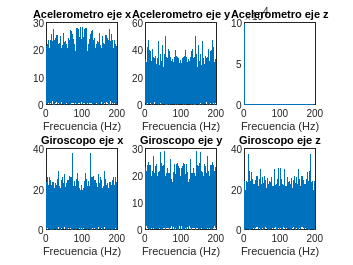

fr = n*200/length(FAc_x);
figure()
subplot(2,3,1)
plot(fr,FAc_x)
title('Acelerometro eje x')
xlabel('Frecuencia (Hz)')
subplot(2,3,2)
plot(fr,FAc_y)
title('Acelerometro eje y')
xlabel('Frecuencia (Hz)')
subplot(2,3,3)
plot(fr,FAc_z)
title('Acelerometro eje z')
xlabel('Frecuencia (Hz)')

subplot(2,3,4)
plot(fr,FGy_x)
title('Giroscopo eje x')
xlabel('Frecuencia (Hz)')
subplot(2,3,5)
plot(fr,FGy_y)
title('Giroscopo eje y')
xlabel('Frecuencia (Hz)')
subplot(2,3,6)
plot(fr,FGy_z)
title('Giroscopo eje z')
xlabel('Frecuencia (Hz)')

Al observar los gráficos de los espectros de frecuencia observará varias cosas:

Existe simetria entre los intervalos 0-100 y 100-200 Hz. Esto se explica porque todas las representaciones frecuenciales de señales de tiempo discreto son periodicas y adicionalmente tienen simetría de números complejos conjugados.

El orden de magnitud (amplitud) es diferente para el Acelerómetro en el eje Z. Este eje es el que está orientado con la gravedad y presenta un nivel DC que se observa en el valor de 0 Hz. Haga zoom a la gráfica de este canal para observar el detalle en las frecuencias diferentes de 0 Hz.

La amplitud representada depende del número de muestras, es decir que entre más muestras se tengan mayor será la amplitud mostrada. Si desea conocer la amplitud de un componente, debe dividir el valor mostrado entre el número de muestras.

Dado que el sensor se encuentra quieto, no se tiene información de movimiento. Entonces lo observado representa el ancho de banda del ruido de adquisición.